# Compile Figures for Synthetic Data

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


%What is your project name?
ProjFolder = 'UK_TempBracket/';

%What is the original data?
originaldata = {'UK_data.txt'};

%do you want the figure saved?
printfig  = true;

%Where do you want to save files?
workdirfigures = '~/Documents/GitHub/Permafrost_ERRA/figures/';

%Where is your data?
workdir = '~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_TempBracket';




%Set directories
workdirfig_ = {workdirfigures, ProjFolder};
workdirfig=char(strcat(workdirfig_(1),workdirfig_(2)));
if ~exist(workdirfig, 'dir')
    cd(workdirfigures)
    mkdir(ProjFolder)
end
cd(workdir)

Get the Temperatures for the range

opts = delimitedTextImportOptions("NumVariables", 12);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["shortt", "shortt_1", "short_t_cont_num", "years", "months", "RH", "airtemp", "dewpoint", "snowdepth", "groundwater", "P", "Q"];
opts.VariableTypes = ["datetime", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "shortt", "InputFormat", "yyyy-MM-dd HH:mm");
opts = setvaropts(opts, "shortt_1", "InputFormat", "yyyy-MM-dd HH:mm");

% Import the data
UKsynthesizeddata = readtable("~/Documents/GitHub/Permafrost_ERRA/rawdata/UK_synthesized_data.txt", opts);

Temperature = table2array(UKsynthesizeddata(:,"airtemp"));


%% Clear temporary variables
clear opts

Lets plot the results

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%FIGURES%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2};
FS = {'FontSize',10,15,18,21,24};
MS = {'MarkerSize',6,8,12};
LS = {'LineStyle','-','--','-.',':'};
% LC = {'Color',color};
color = [252,141,89; 255,255,191; 145,191,219]./255;


%Plotting profiles
axh = 5;
axw = 1.5*axh;
ahs = 0.15;
avs = 0.15;
axb = 0.7;
axt = 0.5;
axl = 1.0;
axr = 0.5;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;


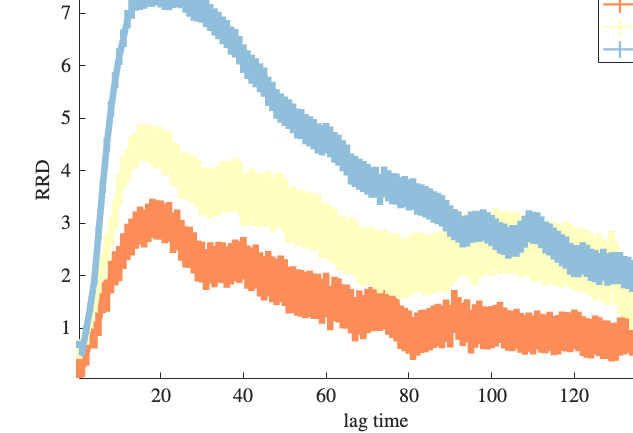


%set figure page
f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

tempbraket = {'l0','04','g4'};
maxRRD = zeros(size(tempbraket));
maxRRDlgt = zeros(size(tempbraket));
% RRD = nan(numel(tempbraket),2000);
% se  = nan(numel(tempbraket),2000);
% lagt = nan(numel(tempbraket),2000);

for jj = 1:numel(tempbraket) 
str = {'1hr_simple_',tempbraket{jj},'_RRD.txt'};
filename=char(strcat(str(1),str(2),str(3)));
[maxRRD(jj),maxRRDlgt(jj),RRD(:,jj),se(:,jj),lagt(:,jj)] = figtRRD_plot_TempBrackets(filename,workdir,color(jj,:));
end





set(gca,'XLim',[min(min(lagt)),max(max(lagt))],'Ylim',[min(min([RRD-se])), max(max([RRD+se]))],TL{:},FS{[1,4]});

%set axis
xlabel('lag time',TX{:},FS{[1,4]},UN{[1,3]});
ylabel('RRD',TX{:},FS{[1,4]},UN{[1,3]});
legend(tempbraket)        
%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'ltRRD' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

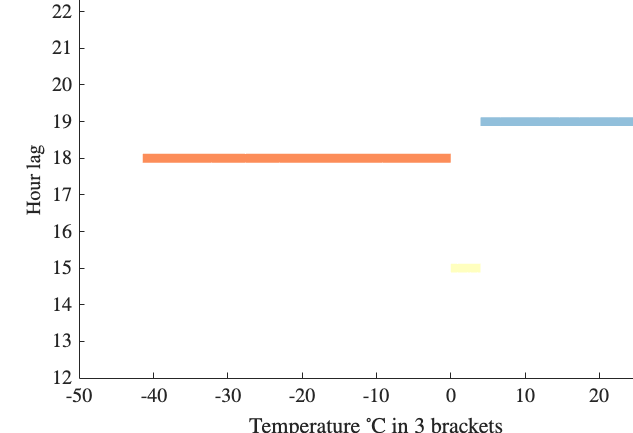

%set figure page
f2 = figure;
set(f2,'Units','Inches','Position',[0.7 12 fw fh]);
set(f2,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f2,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f2,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on
xl0 = linspace(min(Temperature),0,10);
x04 = linspace(0,4,10);
xg4 = linspace(4,max(Temperature),10);
xrow = [xl0; x04; xg4];

for jj = 1:numel(tempbraket)
    plot(xrow(jj,:),maxRRDlgt(jj).*ones(1,10),'-','LineWidth',8,'Color',color(jj,:))
end
xlabel('Temperature $^{\circ}$C in 3 brackets',TX{:},FS{[1,4]},UN{[1,3]})
set(gca,'YLim',[min(maxRRDlgt)-1/5*min(maxRRDlgt),max(maxRRDlgt)+1/5*max(maxRRDlgt)],TL{:},FS{[1,4]});

%set axis
ylabel('Hour lag',TX{:},FS{[1,4]},UN{[1,3]});
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'hourlag' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f2,format,resl,rend,figname,'-loose');
end

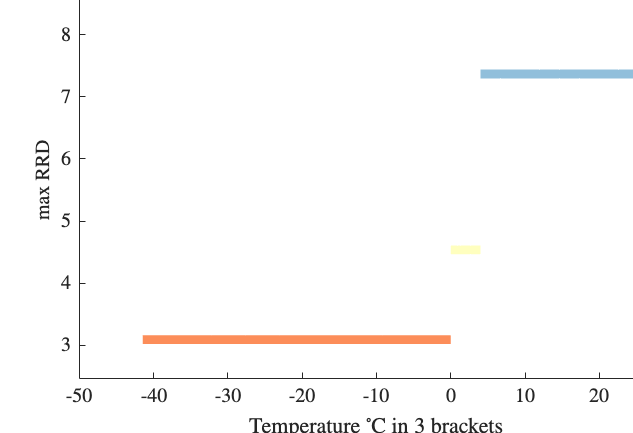

%set figure page
f3 = figure;
set(f3,'Units','Inches','Position',[0.7 12 fw fh]);
set(f3,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f3,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f3,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on
xl0 = linspace(min(Temperature),0,10);
x04 = linspace(0,4,10);
xg4 = linspace(4,max(Temperature),10);
xrow = [xl0; x04; xg4];

for jj = 1:numel(tempbraket)
    plot(xrow(jj,:),maxRRD(jj).*ones(1,10),'-','LineWidth',8,'Color',color(jj,:))
end
xlabel('Temperature $^{\circ}$C in 3 brackets',TX{:},FS{[1,4]},UN{[1,3]})
set(gca,'YLim',[min(maxRRD)-1/5*min(maxRRD),max(maxRRD)+1/5*max(maxRRD)],TL{:},FS{[1,4]});

%set axis
ylabel('max RRD',TX{:},FS{[1,4]},UN{[1,3]});
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'maxRRD' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f3,format,resl,rend,figname,'-loose');
end

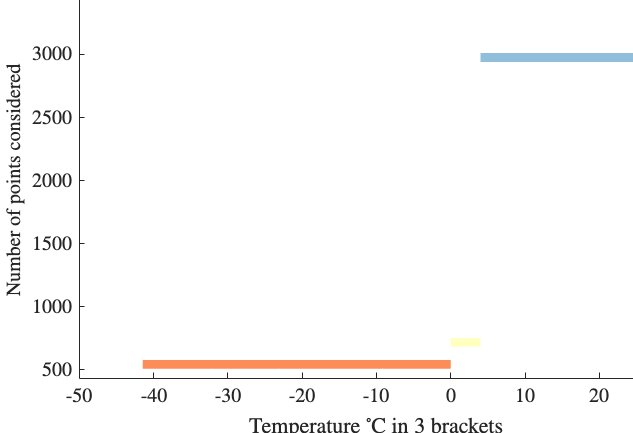

%set figure page
f4 = figure;
set(f4,'Units','Inches','Position',[0.7 12 fw fh]);
set(f4,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f4,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f4,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on
xl0 = linspace(min(Temperature),0,10);
x04 = linspace(0,4,10);
xg4 = linspace(4,max(Temperature),10);
xrow = [xl0; x04; xg4];


for jj = 1:numel(tempbraket)
    str = {'1hr_simple_',tempbraket{jj},'_peakstats.txt'};
    filename=char(strcat(str(1),str(2),str(3)));
    [tpeak(jj), tpeak_se(jj), peakht(jj), peakht_se(jj), width(jj), width_se(jj), rc(jj), rc_se(jj), nz(jj)]...
        = RRD_stats(filename,workdir);
    plot(xrow(jj,:),nz(jj).*ones(1,10),'-','LineWidth',8,'Color',color(jj,:));
end

xlabel('Temperature $^{\circ}$C in 3 brackets',TX{:},FS{[1,4]},UN{[1,3]})
set(gca,'YLim',[min(nz)-1/5*min(nz),max(nz)+1/5*max(nz)],TL{:},FS{[1,4]});

%set axis
ylabel('Number of points considered',TX{:},FS{[1,4]},UN{[1,3]});
  

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'NO_Temp_brackets' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f4,format,resl,rend,figname,'-loose');
end